## get vaccum TF only shot

clear all;
% z t r
% TF 4kV
date = 230125;
shot_num = 3;
low_n_folder = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',num2str(date),'/');

raw_signal = read_datafile(shot_num,low_n_folder);




calib_coefficient = zeros(1,24);
% probe positionによるベクトル方向
direction = ...
   [1,1,1,1,1,1,...
    -1,1,1,-1,1,1,...
    1,1,1,-1,1,1,...
    1,1,1,1,1,1];
for i = 1:8
    calib_coefficient((i-1)*3+1:(i-1)*3+3) = [37.7,41.6,133]*10^-6;
end

RC_data = RC_calibration(24);
% 平均RC = 17.7[ms]

% rearrange to 1-24 in channel number according to labels on cable
B_TF_only(:,1:24) = raw_signal(:,2:25)./calib_coefficient.*direction.*transpose(RC_data);
% offsetを引く
%for i = 1:24
 %     B_TF_only(:,i) = B_TF_only(:,i) - mean(B_TF_only(:,i));
%end

%toroidal_mode_B = toroidal_mode_raw(:,2:25)*1000;
time_array = raw_signal(:,1);


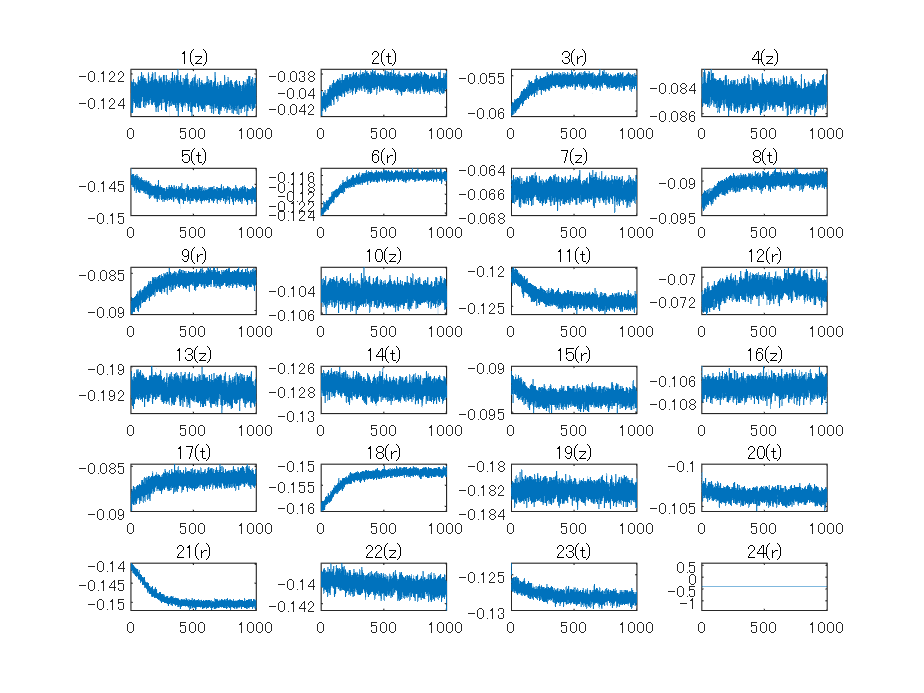

% check all V signals 
% raw signal [mV]
for i = 1:24
    subplot(6,4,i)
    % offsetを0にする
    %raw_signal(:,i+1) = raw_signal(:,i+1) - mean(raw_signal(:,i+1)); 
    plot(time_array,smooth(raw_signal(:,i+1)));
    %xlabel('us');
    %ylabel('mV')
    %xlim([0 50])
    %ylim([-50 50]);
    %
    %ylim([-0.2 0.2])
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end


%ここで変数クリアしているので注意
clearvars -except B_TF_only time_array date shot_num t_start t_end...
    y_upperlim y_lowerlim calib_coefficient B_TF_only low_n_folder raw_signal RC_data

% plotting setting
t_start = 0;
t_end = 1000;

y_upperlim = 400;
y_lowerlim = -400;



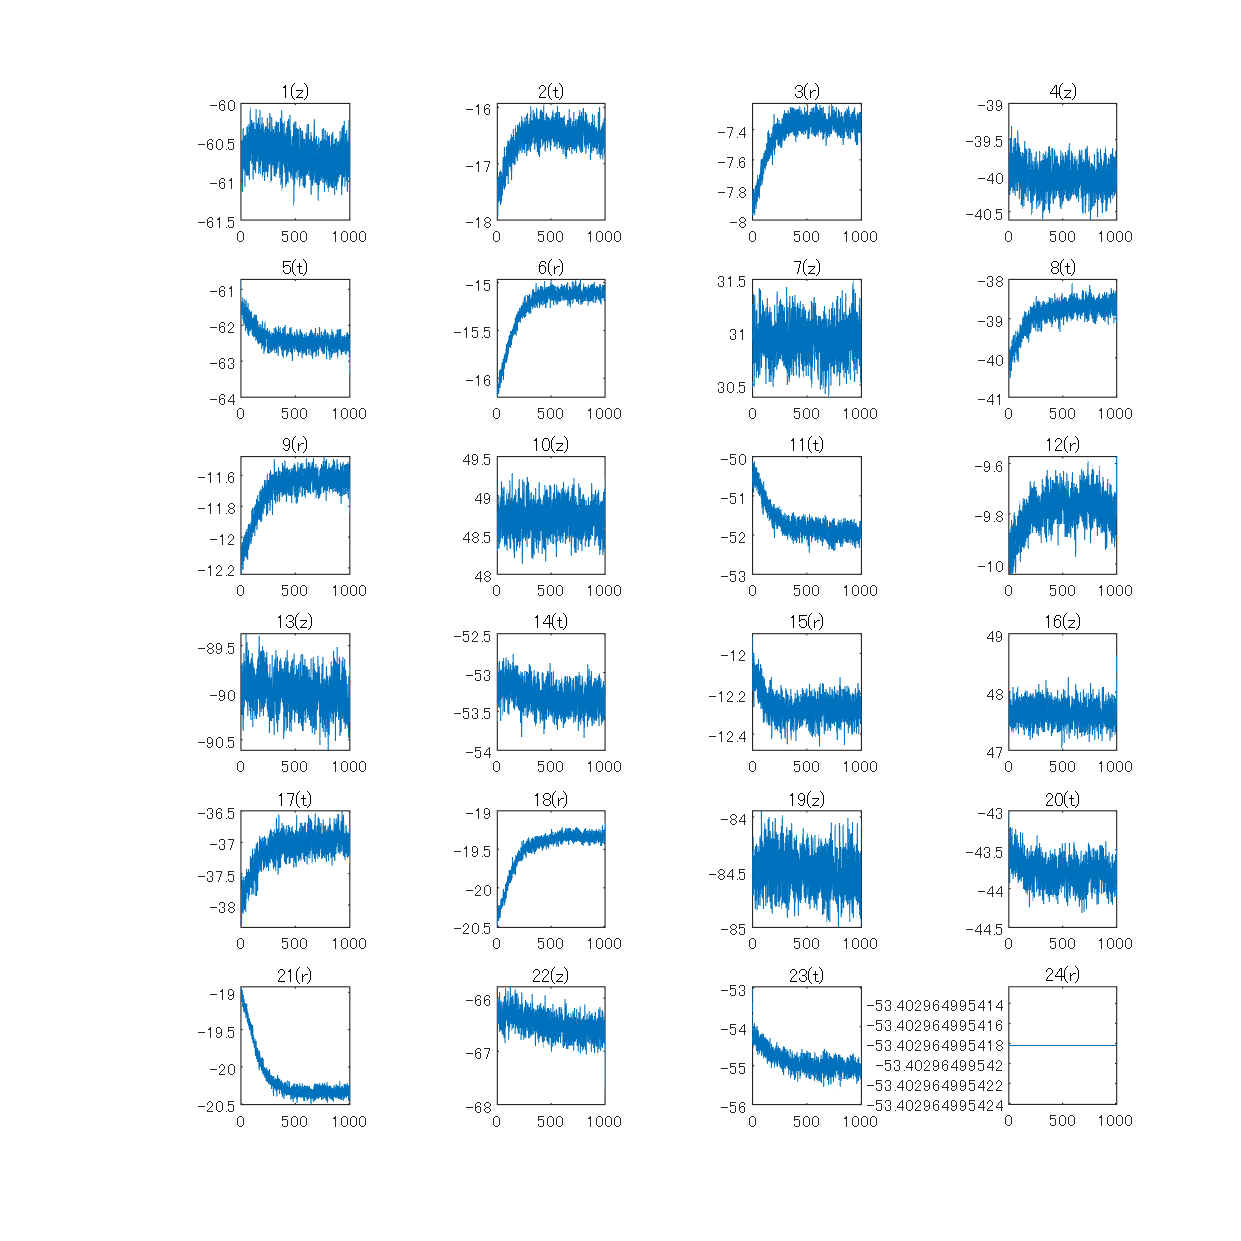

% B signal plot

for i = 1:24
    subplot(6,4,i)
  
    plot(time_array,smooth(B_TF_only(:,i),0.001));
    
    %ylim([-2 2])
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end

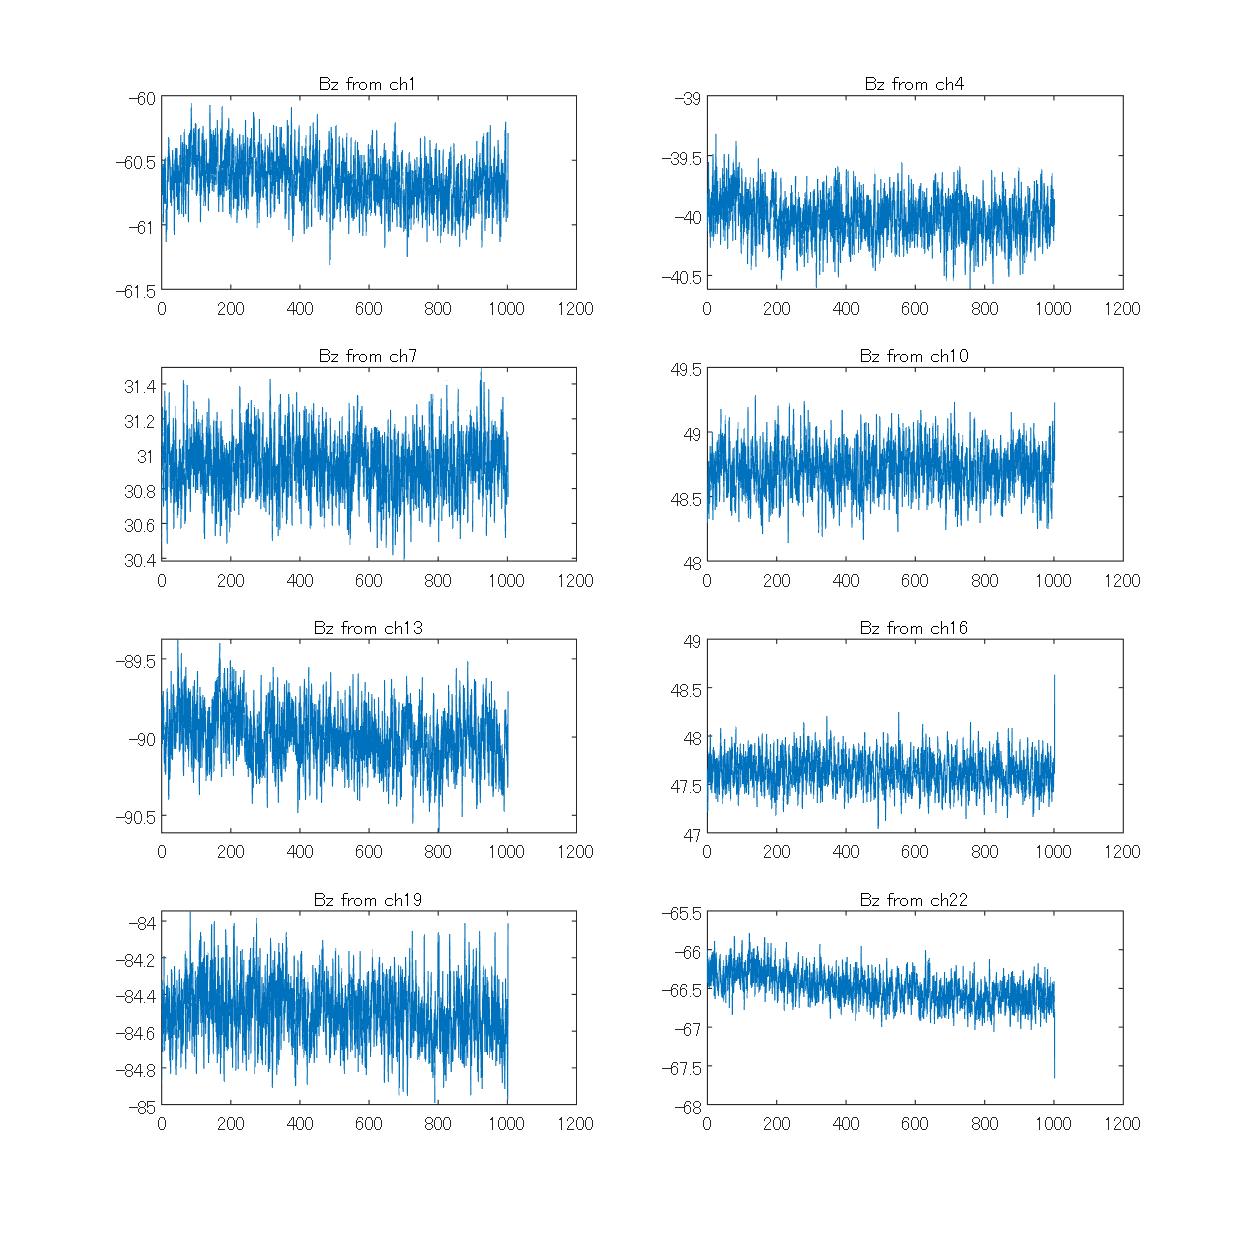

%plot_all_ch(time_array,B_TF_only,t_start, t_end,y_lowerlim, y_upperlim,0.004);
% TFのBz信号のみ
measured_Bz_TF_only = zeros(length(time_array),8);
for i = 1:8
    index_bz = i*3-2;
    measured_Bz_TF_only(:,i) = B_TF_only(:,index_bz);

    subplot(4,2,i)

    plot(time_array,smooth(B_TF_only(:,index_bz),0.001));
    %ylim([-400 400]);
    %ylim([-2 2])
    title(['Bz from ch',num2str(index_bz)])
end

### Btによる較正を試す

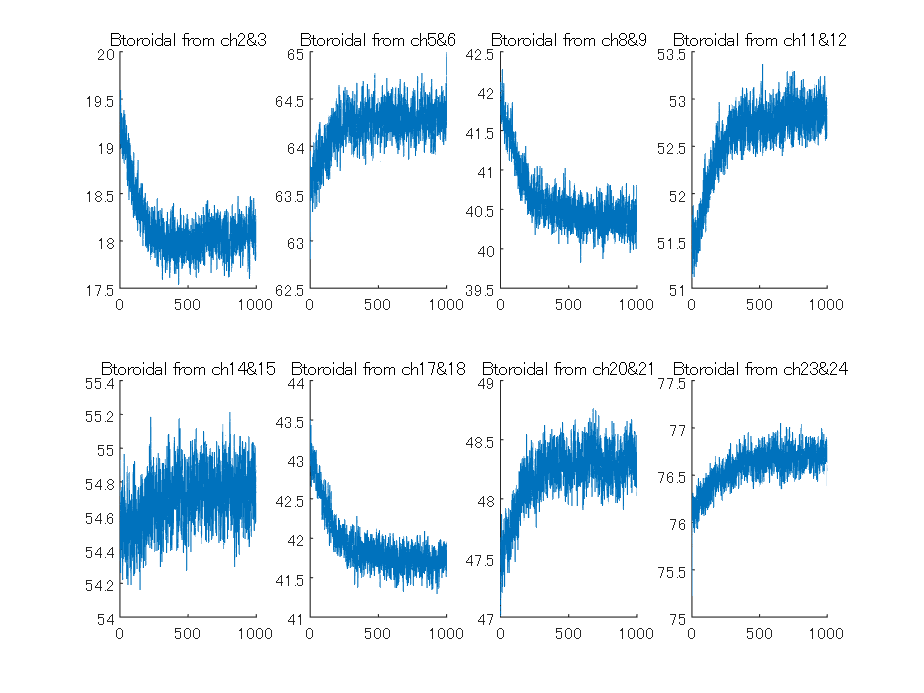

% abs(Btoroidal)がTF only shotで同じかどうか調べてみる
bt_abs = zeros(length(time_array), 8);
figure
for i = 1:8
    subplot(2,4,i)
%     index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    bt_abs(:,i) = sqrt(B_TF_only(:,index_bt).^2+B_TF_only(:,index_br).^2);
    hold on
    plot(time_array,smooth(bt_abs(:,i),0.001));
    hold off
    xlim([t_start t_end])
    %ylim([0 0.15])
    title(['Btoroidal from ch',num2str(index_bt),'&',num2str(index_br)])
end

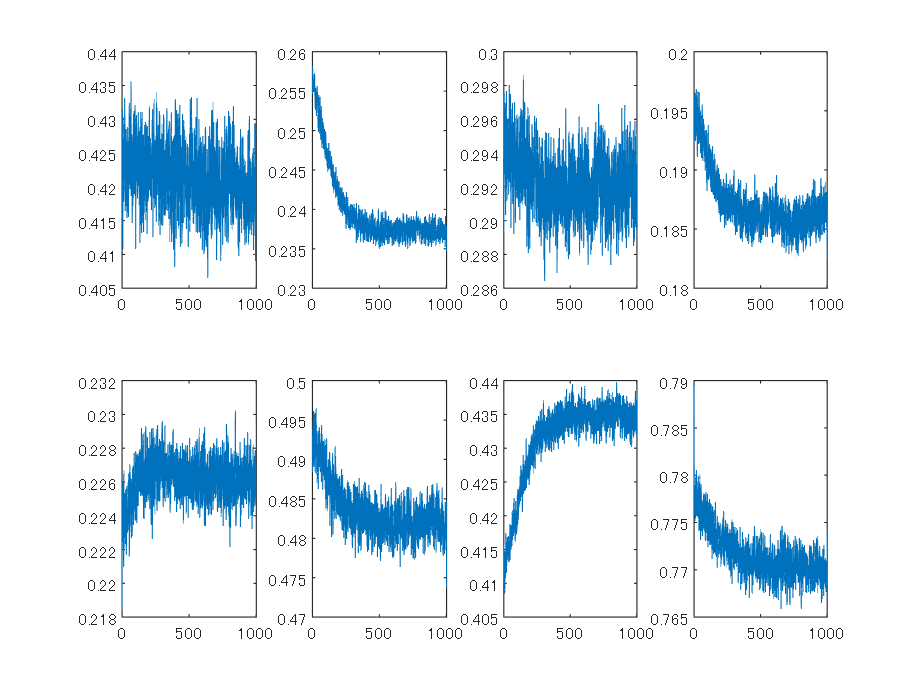

% measured_br = realBt*sin(theta)
% measured_bt = realBt*cos(theta)
% m_br/m_bt = tan(theta)
theta = zeros(length(time_array),8);
for i = 1:8
    index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    theta(:,i) = atan(B_TF_only(:,index_br)./B_TF_only(:,index_bt));
    subplot(2,4,i)
    plot(time_array,smooth(theta(:,i),0.001));
    %ylim([-2 2]);
end

%br-bt平面の傾きの角度の平均値を計算

ave_theta = zeros(8);
ave_theta = mean(theta([6000:10000],:));

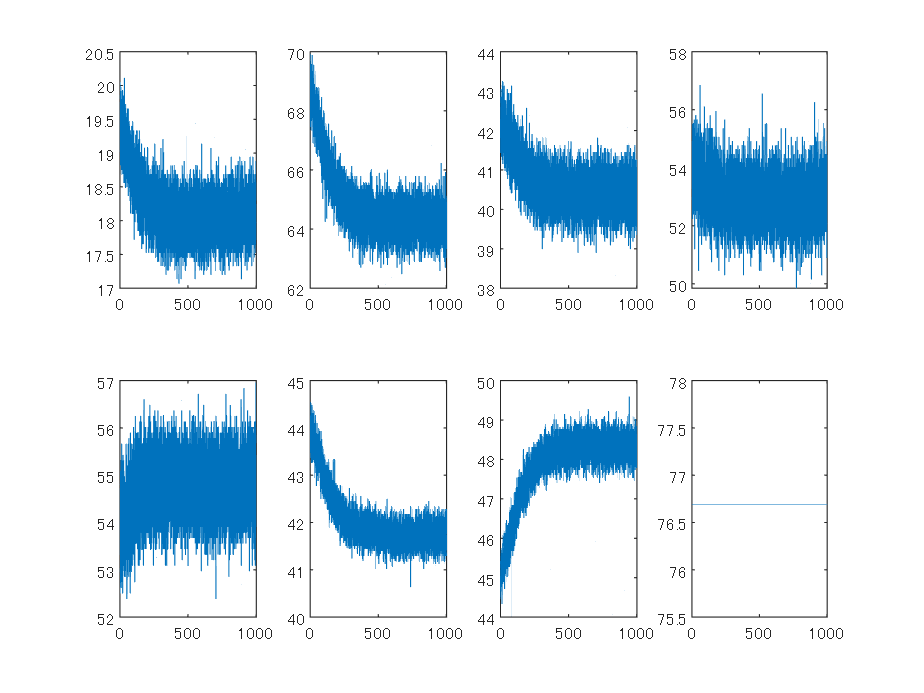

% real_Btの計算
% measured Brからreal Btを求める
real_Bt_from_Br = zeros(length(time_array),8);

for i = 1:8
    index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    
    real_Bt_from_Br(:,i) = B_TF_only(:,index_br)/sin(ave_theta(i));

    subplot(2,4,i)
    plot(time_array,abs(real_Bt_from_Br(:,i)));
    %ylim([0 0.16])
end

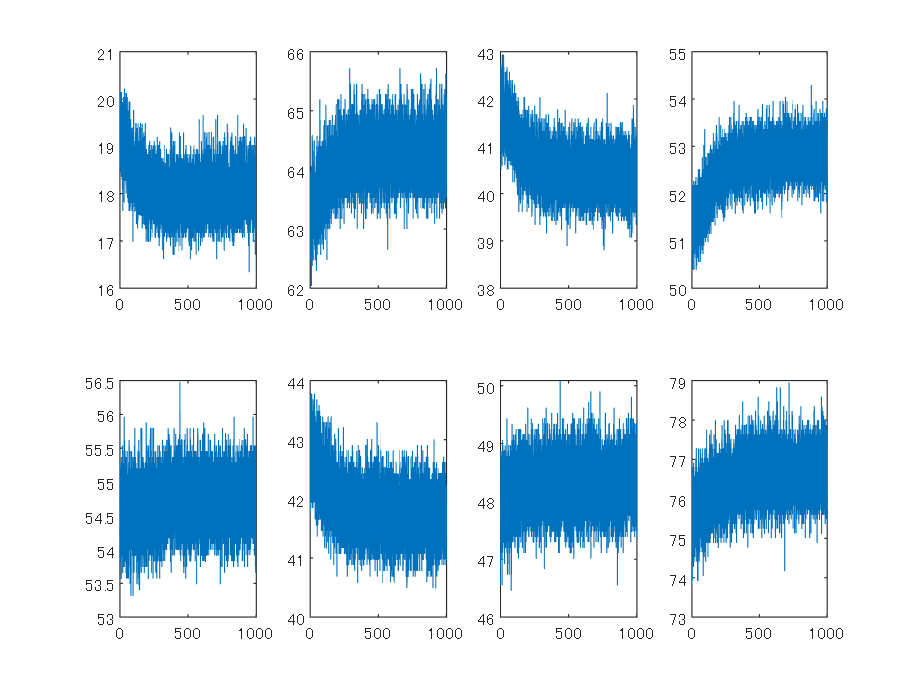


% measured Btからreal_Btを求める
real_Bt_from_Bt = zeros(length(time_array),8);

for i = 1:8
    index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    
    real_Bt_from_Bt(:,i) = B_TF_only(:,index_bt)/cos(ave_theta(i));

    subplot(2,4,i)
    plot(time_array,abs(real_Bt_from_Bt(:,i)));
    %ylim([0 0.16])
end

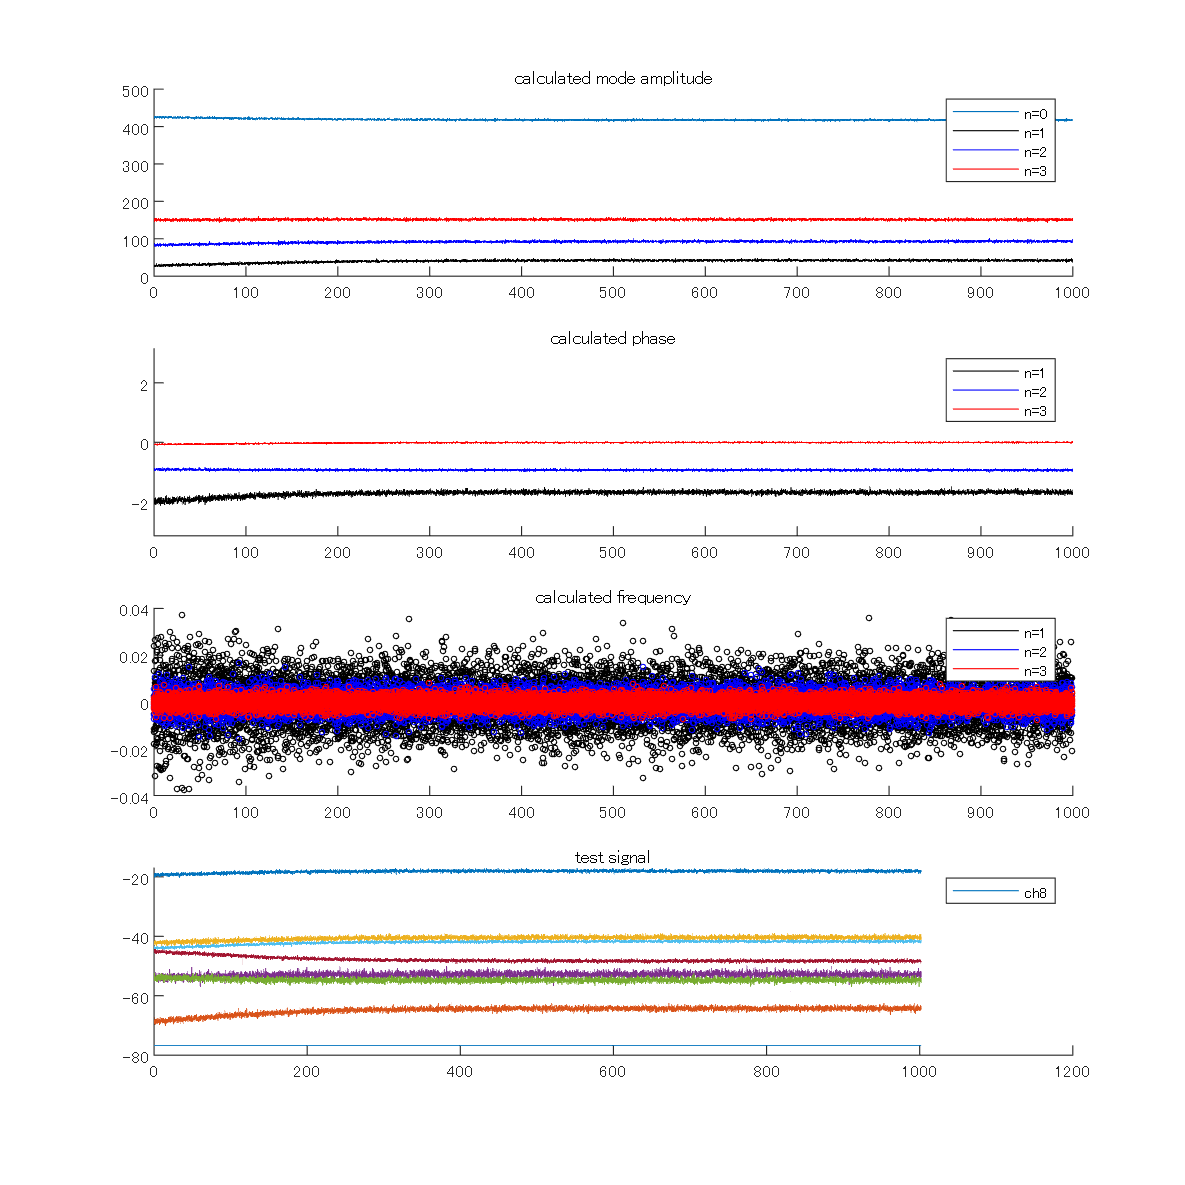

x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);
t = time_array;



%measured_dBzdt = measured_dBzdt(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(t,x,real_Bt_from_Br); % get amplitude and phase
% calculate frequency from phase (smoothed)
n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(4,4,1:4)
hold on
plot(t,n_Amp(1,:));
plot(t,n_Amp(2,:),'k');
plot(t,n_Amp(3,:),'b');
plot(t,n_Amp(4,:),'r');

%plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
% plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
%plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');

%scatter(t,n_Amp(2,:)./n_Amp(1,:),6,'k');
%scatter(t,n_Amp(3,:)./n_Amp(1,:),6,'b');
%scatter(t,n_Amp(4,:)./n_Amp(1,:),6,'r');

%scatter(t,smooth(n_Amp(2,:)./n_Amp(1,:)),6,'k');
%scatter(t,smooth(n_Amp(3,:)./n_Amp(1,:)),6,'b');
%scatter(t,smooth(n_Amp(4,:)./n_Amp(1,:)),6,'r');
legend('n=0','n=1','n=2','n=3');
%ylim([0 20]);
xlim([t_start t_end])
title('calculated mode amplitude')
hold off
subplot(4,4,5:8)
hold on
plot(t,n_Ph(1,:),'k');plot(t,n_Ph(2,:),'b');plot(t,n_Ph(3,:),'r');
plot(t,smooth(n_Ph(1,:),0.01),'k');plot(t,smooth(n_Ph(2,:)),'b');plot(t,smooth(n_Ph(3,:)),'r');
ylim([-pi pi]);
xlim([t_start t_end])
legend('n=1','n=2','n=3');
title('calculated phase')
hold off
subplot(4,4,9:12)
hold on
plot(t,n1_Omega/(2*pi),'k');
plot(t,n2_Omega/(2*pi),'b');
plot(t,n3_Omega/(2*pi),'r');
scatter(t,calculate_omega(cumulative_phase(n_Ph(1,:)))/(2*pi),6,'k');
scatter(t,calculate_omega(cumulative_phase(n_Ph(2,:)))/(2*pi),6,'b');
scatter(t,calculate_omega(cumulative_phase(n_Ph(3,:)))/(2*pi),6,'r');
legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([t_start t_end])
title('calculated frequency')
hold off
subplot(4,4,13:16)
hold on
for i = 1:8
    plot(t,real_Bt_from_Br(:,i));
    legend(['ch',num2str(i)])
    title('test signal')
end
%積分信号のプロット

%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
hold off

clearvars n_Amp n_Ph n1_Omega n2_Omega n3_Omega

### Bzによる較正を試す

% Bzがφだけz軸から傾いている場合,TF真空放電
% (Bz) toroidal_mode_B(:,i*3-1) = real_Bt*sin(phi)

% Bt_vacuum ~= Bt_plasma

% vaccum_TF_onlyのBzを保存
measured_Bz_TF_only = zeros(length(time_array), 8);
for i =1:8
    index_bz = i*3-2;
    measured_Bz_TF_only(:,i) = B_TF_only(:,i*3-2); 
end





%%%%%%%%%%%　Bz_TF_only をノーマルショットから差し引く　%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% z t r
% plasmaあり　TF4kV PF39kV　shotの取得
date = 230125;
shot_num = 11;
raw_signal = read_datafile(shot_num,low_n_folder);


direction = ...
   [1,1,1,1,1,1,...
    -1,1,1,-1,1,1,...
    1,1,1,-1,1,1,...
    1,1,1,1,1,1];
% rearrange to 1-24 in channel number according to labels on cable
B = raw_signal(:,2:25)./calib_coefficient.*direction.*transpose(RC_data);

% offset差し引く
for i = 1:24
     B(:,i) = B(:,i) - mean(B(:,i));
end



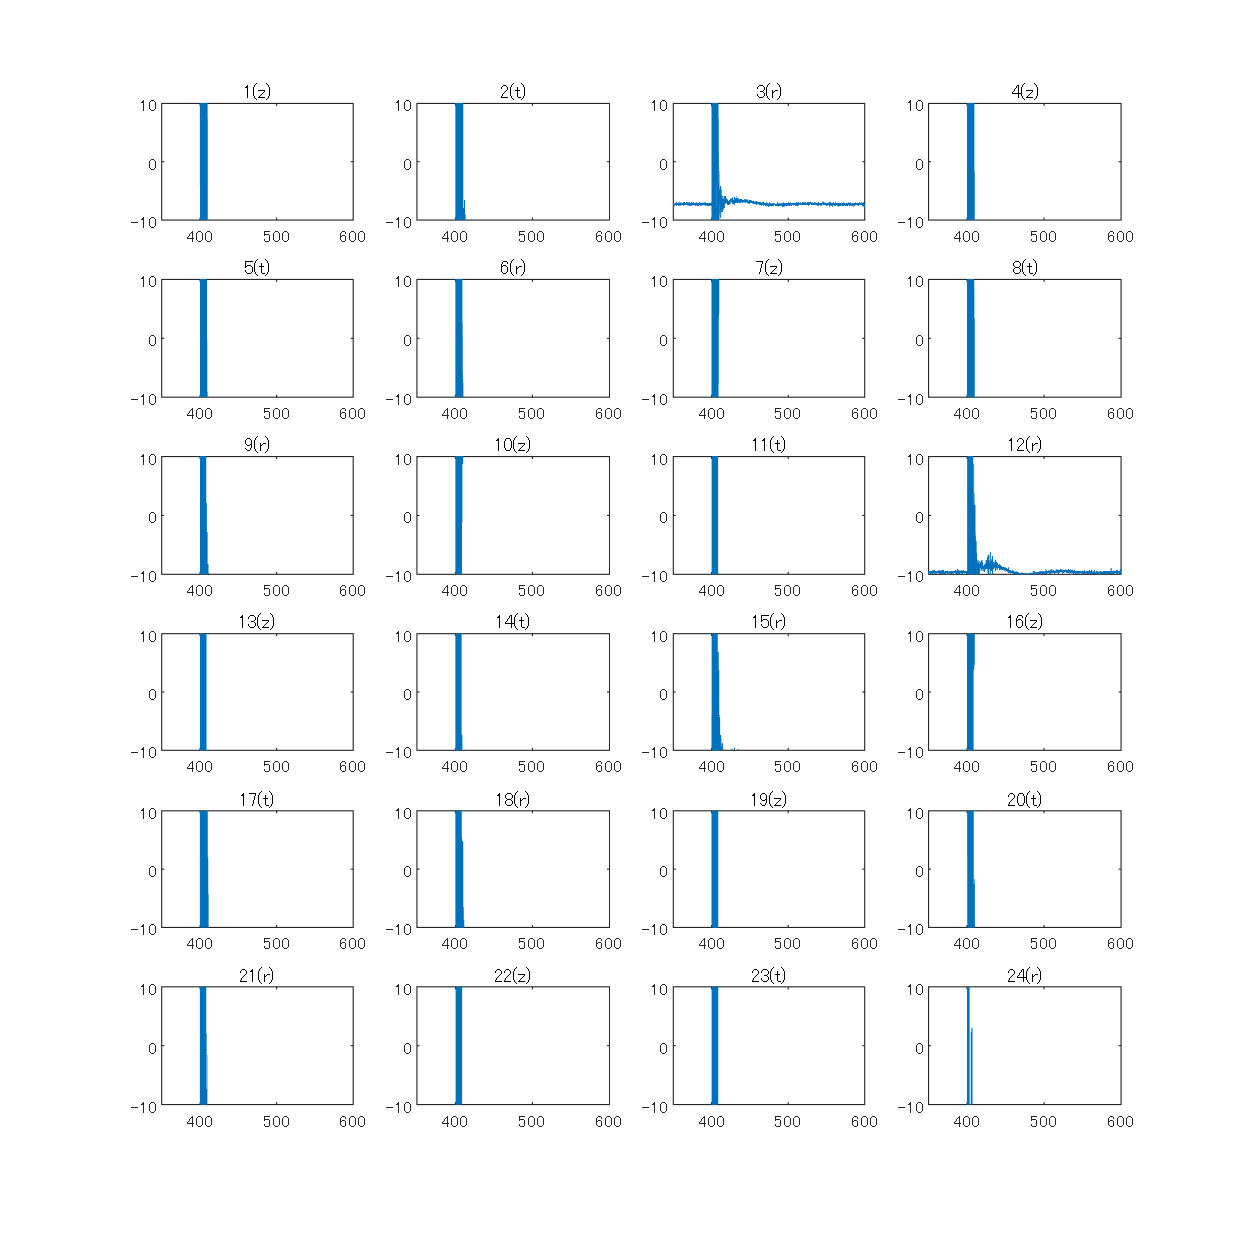

% plot all ch

for i = 1:24
    subplot(6,4,i)
   
    plot(time_array,B(:,i));
    xlim([350 600])
    ylim([-10 10])
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end

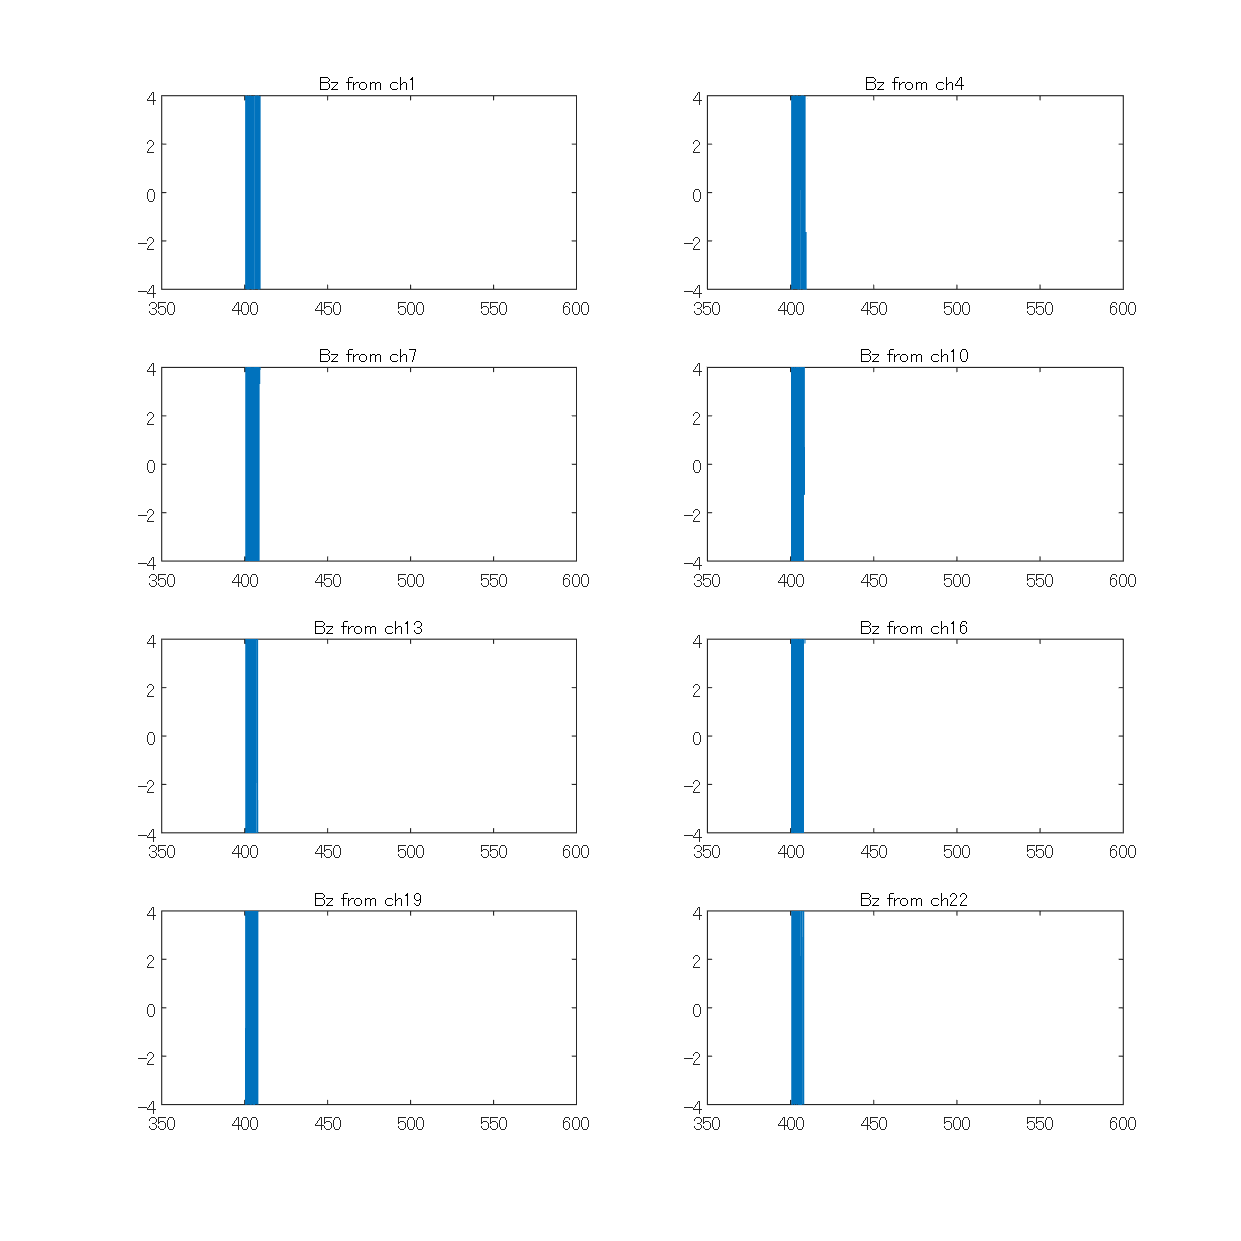


% plot_all_ch(time_array,B,t_start, t_end,y_lowerlim, y_upperlim,0.004);

% Bzのみプロット
for i = 1:8
    index_bz = i*3-2;

    subplot(4,2,i)

    plot(time_array,smooth(B(:,index_bz),0.0001));
    ylim([-4 4]);
    xlim([350 600]);
    title(['Bz from ch',num2str(index_bz)])
end

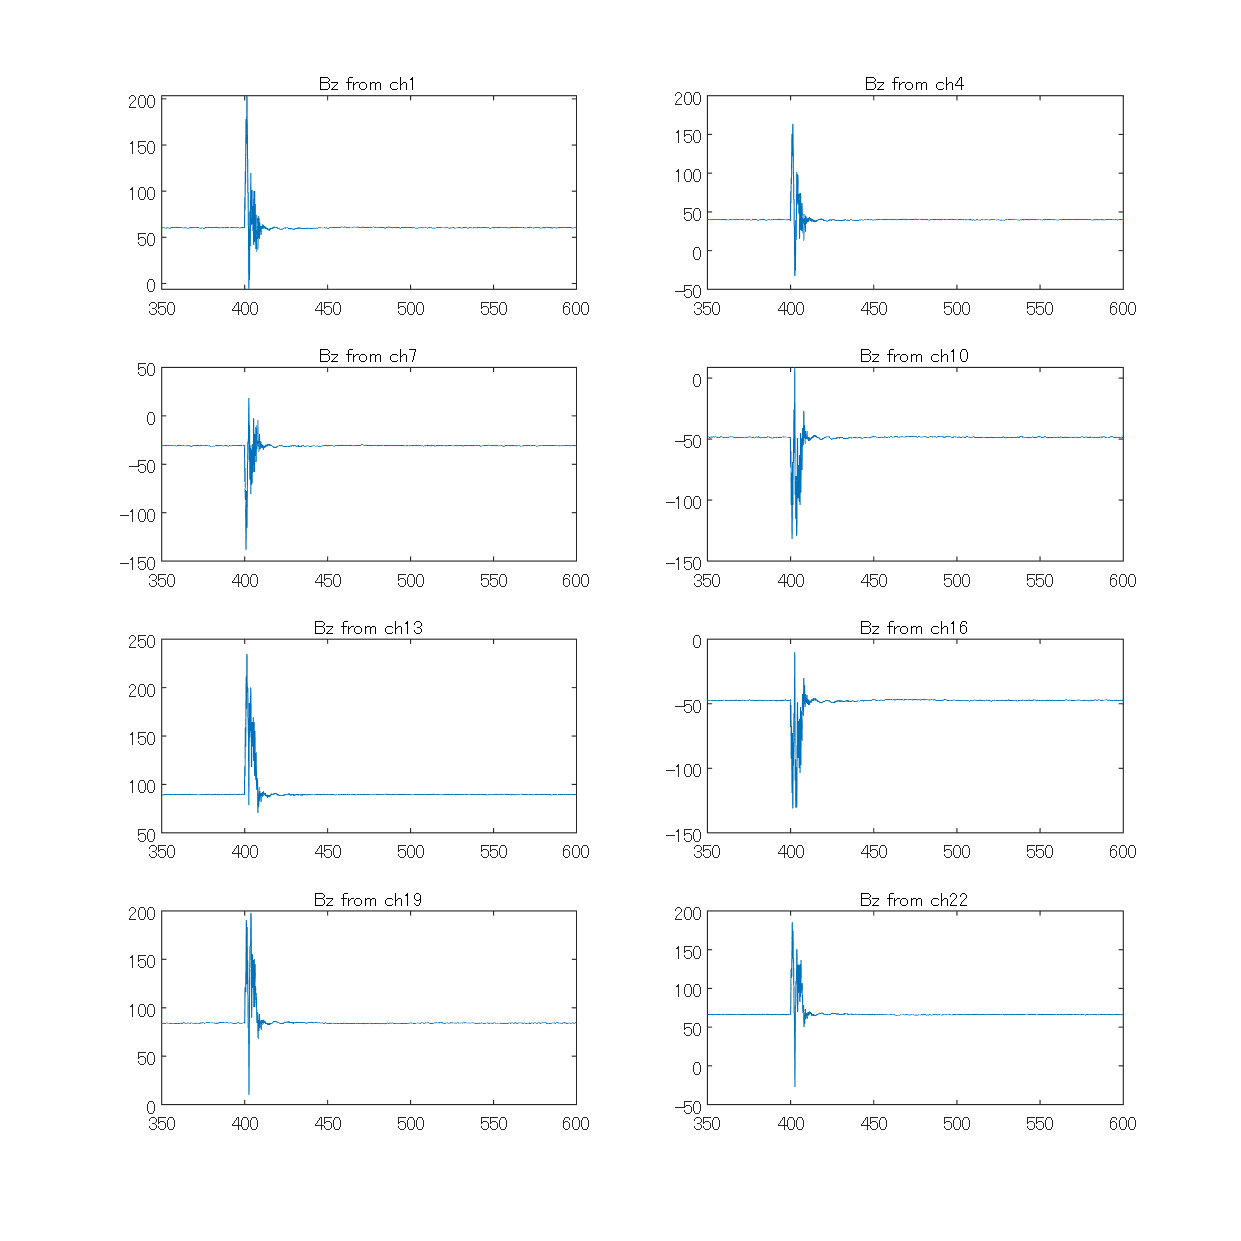

%%%%%%%% Bzを差し引いたものを取得　%%%%%%%%%%
%
measured_Bz = zeros(length(time_array),8);
for i = 1:8

    index_bz = i*3-2;
    measured_Bz(:,i) = B(:,index_bz);
 
  
end

for i = 1:8
    measured_Bz(:, i) = measured_Bz(:, i) - measured_Bz_TF_only(:,i);
    
    subplot(4,2,i)
    plot(time_array, smooth(measured_Bz(:, i),0.001));
    xlim([350 600])
    %ylim([-4 4])
    %ylim([-6000 6000]);
    title(['Bz from ch',num2str(i*3-2)]);
end

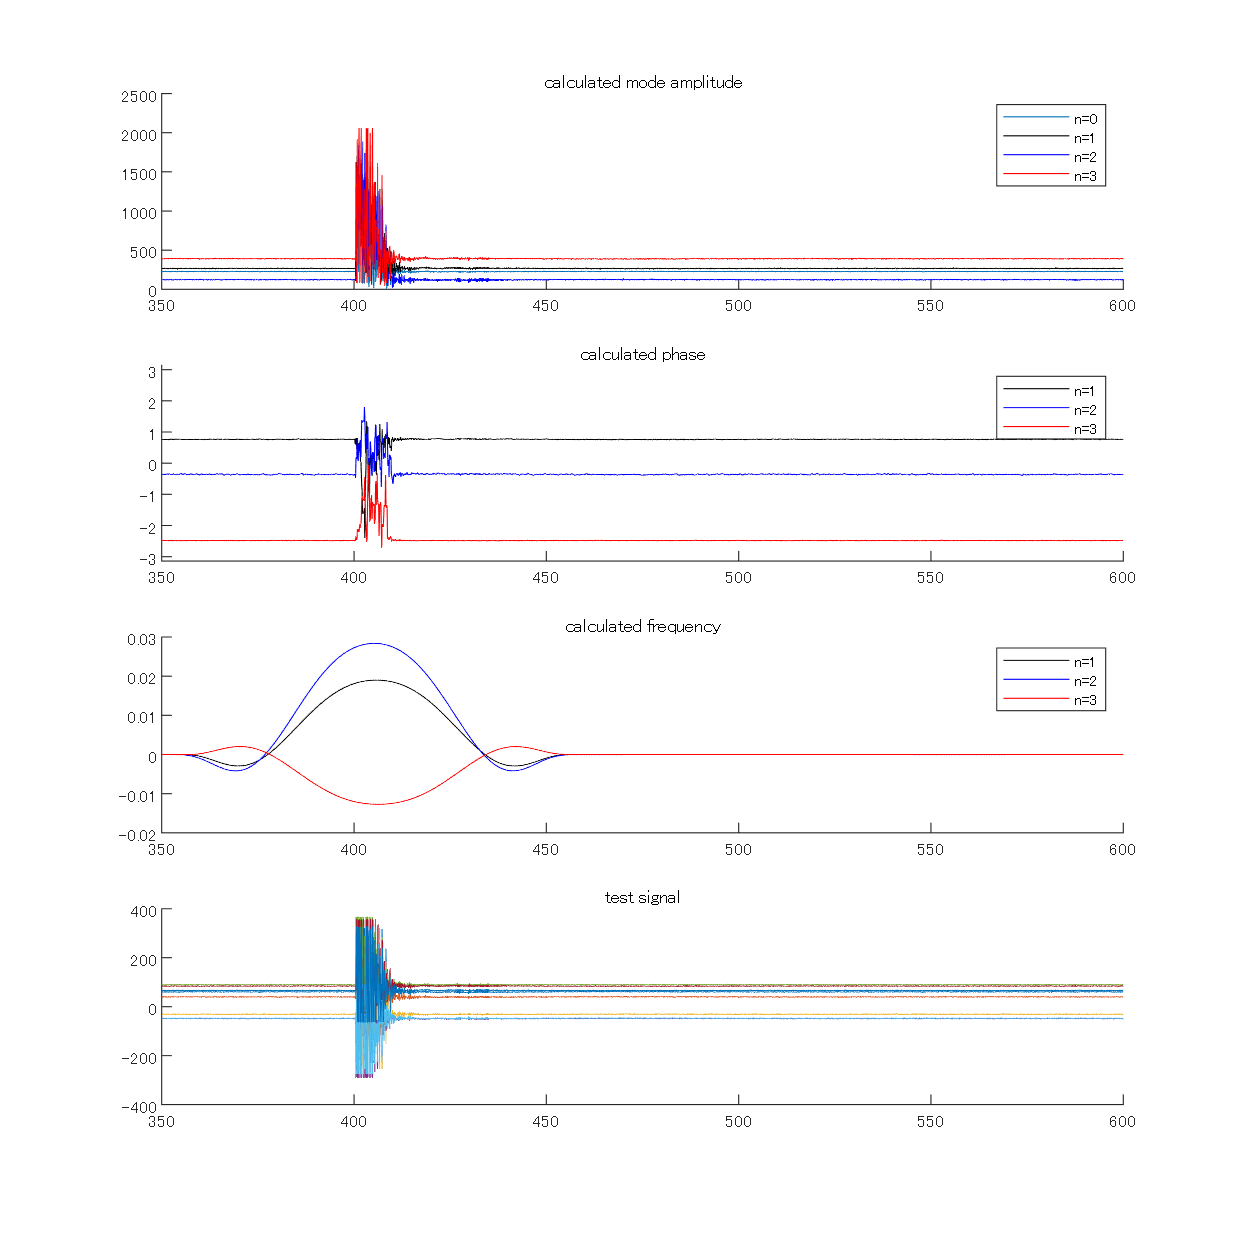

t_start = 350;
t_end = 600;
t = time_array;

x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);


%measured_dBzdt = measured_dBzdt(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(time_array,x,measured_Bz); % get amplitude and phase
% calculate frequency from phase (smoothed)
n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(4,4,1:4)
hold on
plot(t,n_Amp(1,:));
plot(t,n_Amp(2,:),'k');
plot(t,n_Amp(3,:),'b');
plot(t,n_Amp(4,:),'r');
%plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
%plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
%plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
%scatter(t,n_Amp(2,:)./n_Amp(1,:),6,'k');
%scatter(t,n_Amp(3,:)./n_Amp(1,:),6,'b');
%scatter(t,n_Amp(4,:)./n_Amp(1,:),6,'r');

%scatter(t,smooth(n_Amp(2,:)./n_Amp(1,:)),6,'k');
%scatter(t,smooth(n_Amp(3,:)./n_Amp(1,:)),6,'b');
%scatter(t,smooth(n_Amp(4,:)./n_Amp(1,:)),6,'r');
legend('n=0','n=1','n=2','n=3');
%ylim([0 50])
xlim([t_start t_end])
title('calculated mode amplitude')
hold off
subplot(4,4,5:8)
hold on
%plot(t,n_Ph(1,:),'k');plot(t,n_Ph(2,:),'b');plot(t,n_Ph(3,:),'r');
plot(t,smooth(n_Ph(1,:)),'k');plot(t,smooth(n_Ph(2,:)),'b');plot(t,smooth(n_Ph(3,:)),'r');
ylim([-pi pi]);
xlim([t_start t_end])
legend('n=1','n=2','n=3');
title('calculated phase')
hold off
subplot(4,4,9:12)
hold on
plot(t,n1_Omega/(2*pi),'k');
plot(t,n2_Omega/(2*pi),'b');
plot(t,n3_Omega/(2*pi),'r');
%scatter(t,calculate_omega(cumulative_phase(n_Ph(1,:)))/(2*pi),6,'k');
%scatter(t,calculate_omega(cumulative_phase(n_Ph(2,:)))/(2*pi),6,'b');
%scatter(t,calculate_omega(cumulative_phase(n_Ph(3,:)))/(2*pi),6,'r');
legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([t_start t_end])
title('calculated frequency')
hold off
subplot(4,4,13:16)
hold on
for i = 1:8
    plot(t,measured_Bz(:,i));
    xlim([t_start t_end]);
    title('test signal')
end
%積分信号のプロット

%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
%ylim([0 2000])
hold off

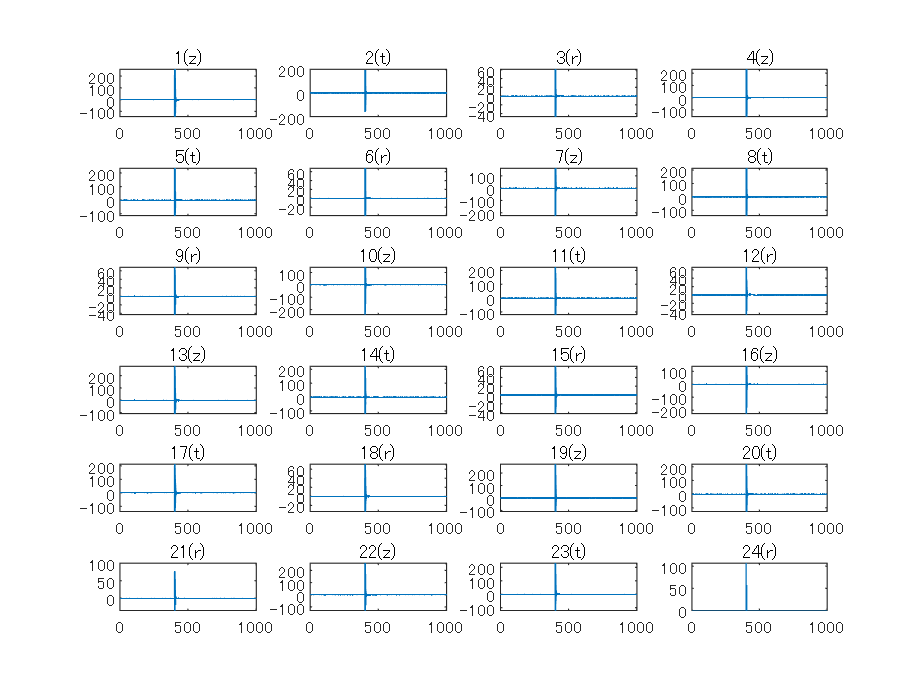

figure
for i = 1:24
    subplot(6,4,i)
    plot(time_array,B(:,i));
    %xlim([t_start t_end])
    %ylim([-1 1])
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end

### Bpのプローブごとの比較

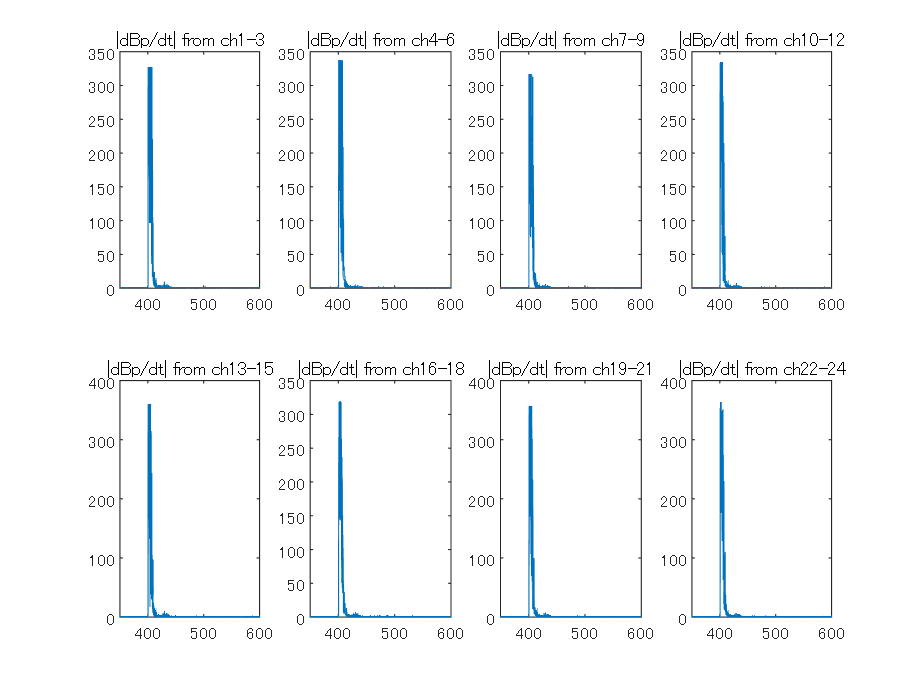

figure
for i = 1:8
    subplot(2,4,i)
    index_bz = i*3-2;
    index_bt = i*3-1;
    index_br = i*3;
    bp_abs = sqrt(B(:,index_bz).^2 + B(:,index_br).^2 + B(:,index_bt).^2);
    plot(time_array,bp_abs);
    xlim([t_start t_end])
    %ylim([y_lowerlim y_upperlim])
    %ylim([0 500])
    title(['|dBp/dt| from ch',num2str(index_bz),'-',num2str(index_br)])
end

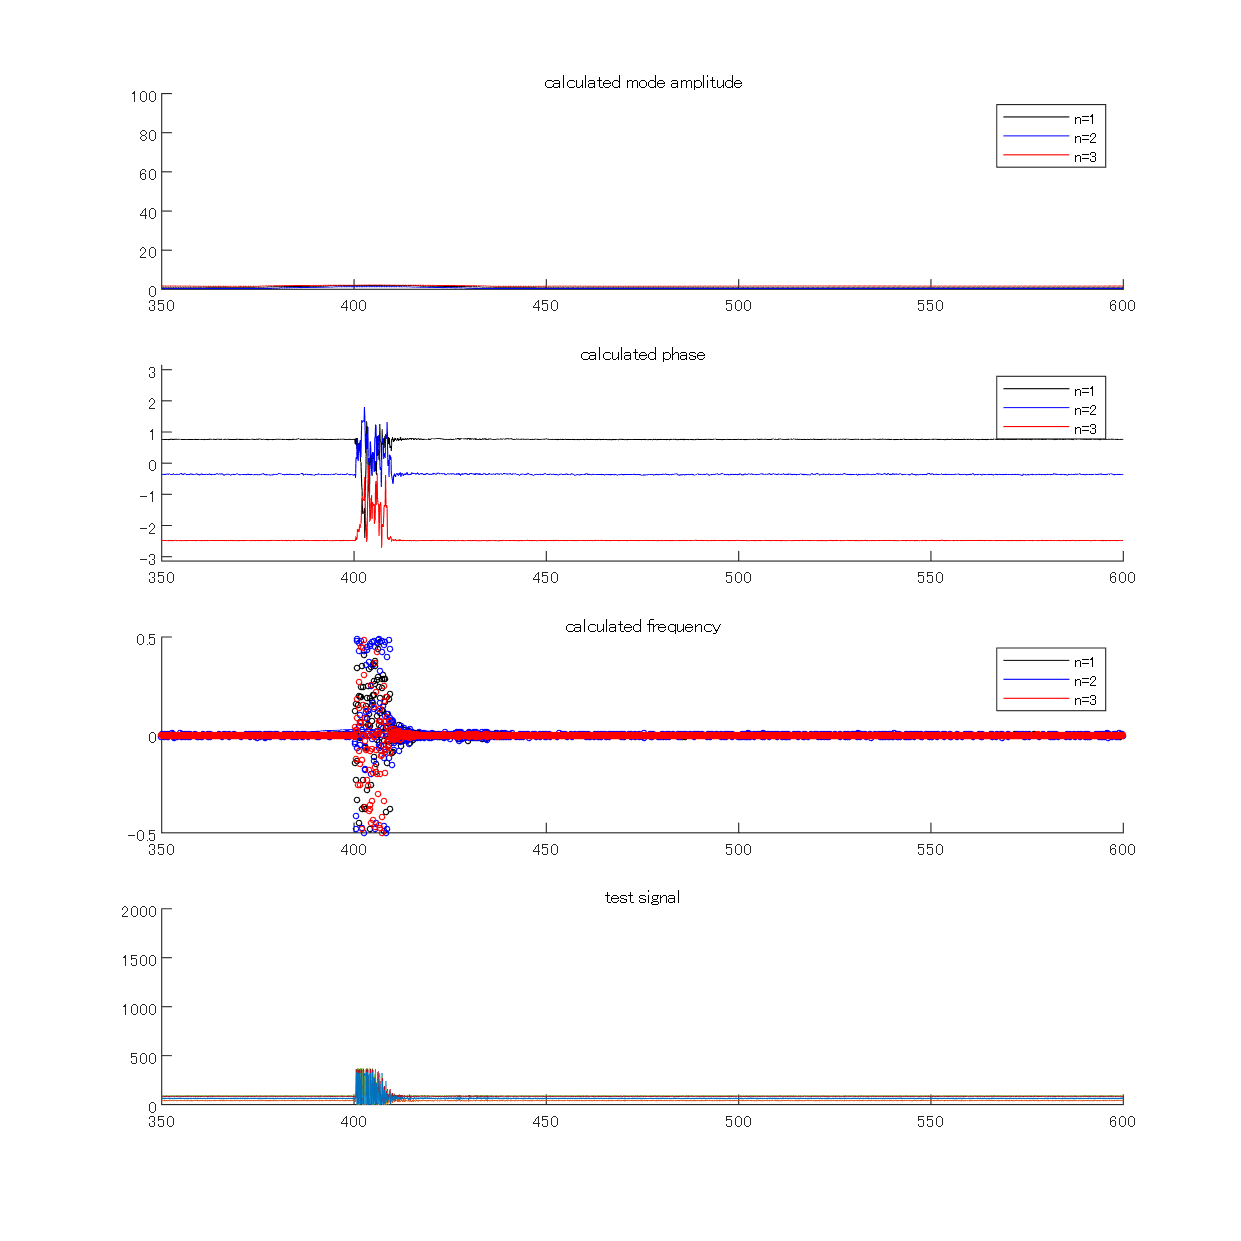




x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);
t = time_array;

%measured_dBzdt = measured_dBzdt(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(t,x,measured_Bz); % get amplitude and phase
% calculate frequency from phase (smoothed)
n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(4,4,1:4)
hold on
plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
%scatter(t,n_Amp(2,:)./n_Amp(1,:),6,'k');
%scatter(t,n_Amp(3,:)./n_Amp(1,:),6,'b');
%scatter(t,n_Amp(4,:)./n_Amp(1,:),6,'r');

%scatter(t,smooth(n_Amp(2,:)./n_Amp(1,:)),6,'k');
%scatter(t,smooth(n_Amp(3,:)./n_Amp(1,:)),6,'b');
%scatter(t,smooth(n_Amp(4,:)./n_Amp(1,:)),6,'r');
legend('n=1','n=2','n=3');
ylim([0 100]);
xlim([t_start t_end])
title('calculated mode amplitude')
hold off
subplot(4,4,5:8)
hold on
%plot(t,n_Ph(1,:),'k');plot(t,n_Ph(2,:),'b');plot(t,n_Ph(3,:),'r');
plot(t,smooth(n_Ph(1,:)),'k');plot(t,smooth(n_Ph(2,:)),'b');plot(t,smooth(n_Ph(3,:)),'r');
ylim([-pi pi]);
xlim([t_start t_end])
legend('n=1','n=2','n=3');
title('calculated phase')
hold off
subplot(4,4,9:12)
hold on
plot(t,n1_Omega/(2*pi),'k');
plot(t,n2_Omega/(2*pi),'b');
plot(t,n3_Omega/(2*pi),'r');
scatter(t,calculate_omega(cumulative_phase(n_Ph(1,:)))/(2*pi),6,'k');
scatter(t,calculate_omega(cumulative_phase(n_Ph(2,:)))/(2*pi),6,'b');
scatter(t,calculate_omega(cumulative_phase(n_Ph(3,:)))/(2*pi),6,'r');
legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([t_start t_end])
title('calculated frequency')
hold off
subplot(4,4,13:16)
hold on
for i = 1:8
    plot(t,measured_Bz(:,i));
    xlim([t_start t_end]);
    title('test signal')
end
%積分信号のプロット

%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
ylim([0 2000])
hold off